# Example: Formal Verification of MNIST Images

The following example shows how we can formally verify a neural network given uncertainty in the input.

Let us first load the dataset and the neural network into MATLAB:

% load MNIST dataset (required Deep Learning Toolbox)
[XTest,YTest] = digitTest4DArrayData;

% load neural network
modelfile = "mnist_sigmoid_6_200.onnx";
nn = neuralNetwork.readONNXNetwork(modelfile, false, 'BCSS');

Next, we select an image and test if the network is classifying it correctly:

% sample image
idx = 2002; % 2002
x = XTest(:,:,:,idx);           % image
target = double(YTest(idx))-1;   % label (dim=1 is label=0)

% reshape image to vector to be consistent with set definitions
c = reshape(x,[],1);

% propagate through network
y_pred = nn.evaluate(c);
[~,label_pred] = max(y_pred);
label_pred = label_pred - 1;
fprintf("Correct classification: %d\n", target == label_pred);

Correct classification: 1


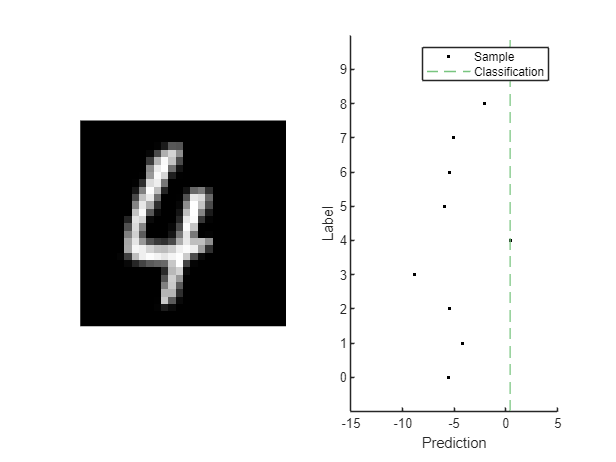

% plot
figure;
subplot(1,2,1);
imshow(x);

subplot(1,2,2); hold on
labels = 0:9;
handleVis = ["on","off"];
for label=labels
    scatter(y_pred(label+1,:),label,'.k','DisplayName','Sample','HandleVisibility',handleVis((label > 0) + 1))
end
plot(ones(2,1).* y_pred(target+1,:),[-1,10],'--','Color',CORAcolor('CORA:safe'),'DisplayName','Classification');
xlim([-15,5]); ylim([-1,10]); yticks(labels);
ylabel('Label'); xlabel('Prediction');
legend()

As the prediction of the correct label is larger than all other predictions, the image is correctly classified by the neural network.

However, this approach no longer works if the input is uncertain, i.e. each pixel can be perturbed up to a perturbation radius $\epsilon$. Let us demonstrate this by the following example:

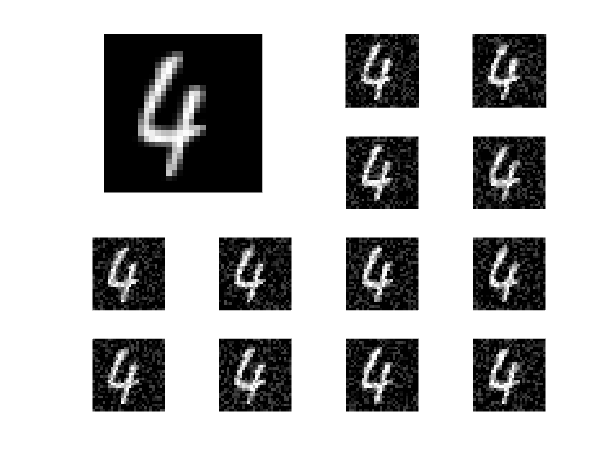

% init uncertain input
epsilon = 0.3;
X = interval(c-epsilon,c+epsilon);

% gather samples
N = 50;
xs = X.randPoint(N);

% plot images
figure;
subplot(2,2,1); imshow(reshape(c,28,28));
idx = [3,4,7:16];
for i=1:length(idx)
    subplot(4,4,idx(i)); imshow(reshape(xs(:,i),28,28));
end

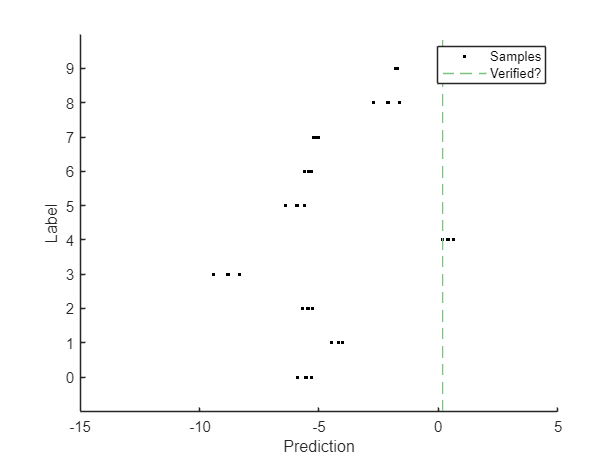

% reduce uncertain input for verification
epsilon = 0.001;
X = interval(c-epsilon,c+epsilon);

% gather samples
N = 50;
xs = X.randPoint(N-2);
% perform fgsm attack
S = nn.calcSensitivity(c); 
fgsm = sign(mean(sign(S)))' * epsilon;
xs = [xs,c+fgsm,c-fgsm];
% propagate samples through neural network
ys_pred = nn.evaluate(xs);

% plot
figure; hold on
labels = 0:9;
handleVis = ["on","off"];
for label=labels
    scatter(ys_pred(label+1,:),label .* ones(N,1),'.k','DisplayName','Samples','HandleVisibility',handleVis((label > 0) + 1))
end
plot(min(ys_pred(target+1,:)) .* ones(2,1),[-1,10],'--','Color',CORAcolor('CORA:safe'),'DisplayName','Verified?');
xlim([-15,5]); ylim([-1,10]); yticks(labels);
ylabel('Label'); xlabel('Prediction');
legend()

Unfortunately, we cannot reason about the correct classification of the entire input set by just looking at samples as we might miss outliers.

Thus, we can conservativly propagate the set itself through the network using CORA. If the lower bound of the target label is larger than the upper bound of all other labels, we have formually proven that all images are classified correctly given the noise radius $\epsilon$.

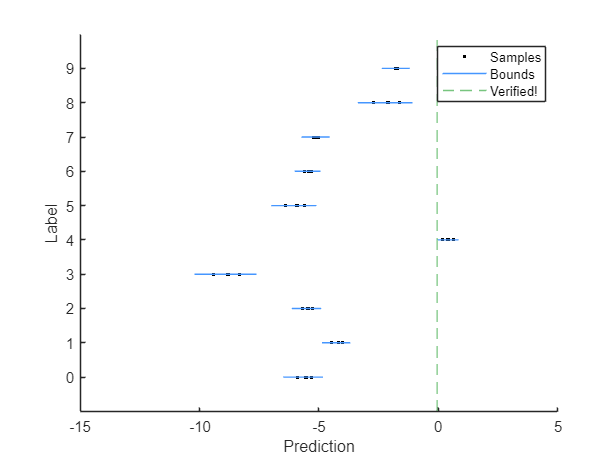

% propagate uncertain input set through the network
Y_pred = nn.evaluate(zonotope(X));

% plot
figure; hold on
labels = 0:9;
handleVis = ["on","off"];
for label=labels
    scatter(ys_pred(label+1,:),label .* ones(N,1),'.k','DisplayName','Samples','HandleVisibility',handleVis((label > 0) + 1))
    plot(Y_pred,label+1,'YPos',label,'DisplayName','Bounds','HandleVisibility',handleVis((label > 0) + 1),'Color',CORAcolor('CORA:reachSet'))
end
plot(interval(Y_pred).inf(target+1,:) .* ones(2,1),[-1,10],'--','Color',CORAcolor('CORA:safe'),'DisplayName','Verified!');
xlim([-15,5]); ylim([-1,10]); yticks(labels);
ylabel('Label'); xlabel('Prediction');
legend()

Finally, as the notion of the lower bound of the target label being larger than the upper bound of all other labels is a bit tedious, we can transform the output space to have the target output always at 0 and all other bounds should be below zero. This allows a simple verification check algorithmically and visually as given below:

% init transformation matrix
T = eye(10);
T(:,target+1) = T(:,target+1)-1;

% transform
Y_pred = T*Y_pred;
ys_pred = T*ys_pred;

% define unsafe set as specification
spec = specification(polytope(-eye(10),zeros(10,1)),'unsafeSet');

% check specification
fprintf("Check samples: %d\n", check(spec,ys_pred));

Check samples: 1


fprintf("Verification: %d\n", check(spec,Y_pred));

Verification: 1


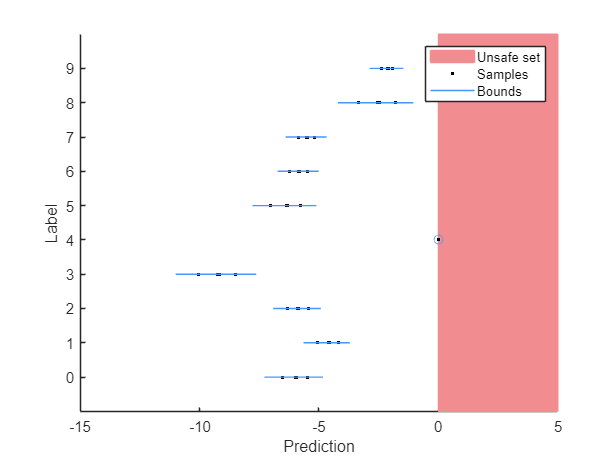


% plot
figure; hold on
xlim([-15,5]); ylim([-1,10]); yticks(labels);
plot(specification(polytope([-1,0],0),'unsafeSet'),1:2,'DisplayName','Unsafe set')
labels = 0:9;
handleVis = ["on","off"];
for label=labels
    scatter(ys_pred(label+1,:),label .* ones(N,1),'.k','DisplayName','Samples','HandleVisibility',handleVis((label > 0) + 1))
    plot(Y_pred,label+1,'YPos',label,'DisplayName','Bounds','HandleVisibility',handleVis((label > 0) + 1),'Color',CORAcolor('CORA:reachSet'))
end
xlim([-15,5]); ylim([-1,10]); yticks(labels);
ylabel('Label'); xlabel('Prediction');
legend()

exportToHTML(); % for website